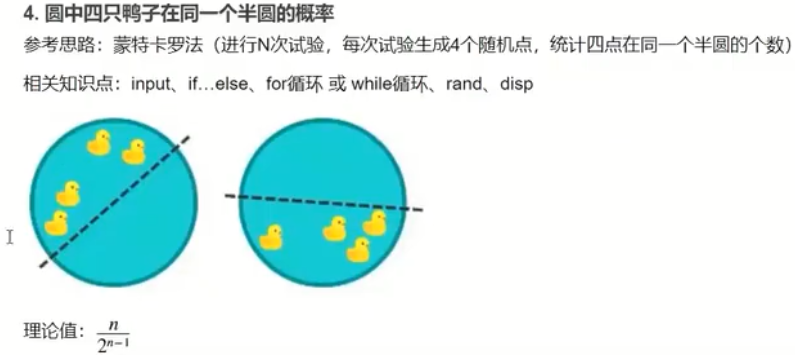

分析

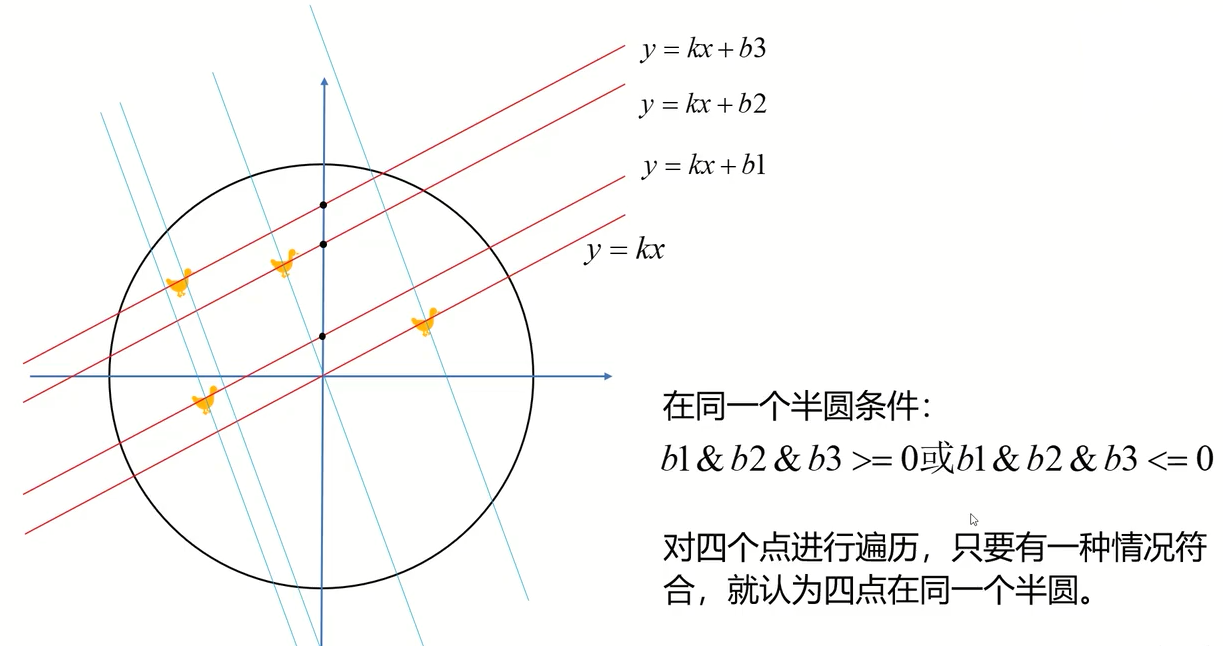

1.思路简单易实现，但不优雅

N=4;
total=100000;
count=0;
for e=1:total
    p1=2*[rand,rand]-1;
    p2=2*[rand,rand]-1;
    p3=2*[rand,rand]-1;
    p4=2*[rand,rand]-1;
    %p1作为第一点计算斜率，其余点计算截距
    k=p1(2)/p1(1);%纵坐标除横坐标
    b1=p2(2)-k*p2(1);
    b2=p3(2)-k*p3(1);
    b3=p4(2)-k*p4(1);

    if (b1>=0&b2>=0&b3>=0)|(b1<=0&b2<=0&b3<=0)
        count=count+1;
        continue;
    end
    %p2作为第一点计算斜率，其余点计算截距
    k=p2(2)/p2(1);
    b1=p1(2)-k*p1(1);
    b2=p3(2)-k*p3(1);
    b3=p4(2)-k*p4(1);

    if (b1>=0&b2>=0&b3>=0)|(b1<=0&b2<=0&b3<=0)
        count=count+1;
        continue;
    end
    %p3作为第一点计算斜率，其余点计算截距
    k=p3(2)/p3(1);
    b1=p2(2)-k*p2(1);
    b2=p1(2)-k*p1(1);
    b3=p4(2)-k*p4(1);

    if (b1>=0&b2>=0&b3>=0)|(b1<=0&b2<=0&b3<=0)
        count=count+1;
        continue;
    end
    %p4作为第二点计算斜率，其余点计算截距
    k=p3(2)/p3(1);
    b1=p2(2)-k*p2(1);
    b2=p3(2)-k*p3(1);
    b3=p1(2)-k*p1(1);

    if (b1>=0&b2>=0&b3>=0)|(b1<=0&b2<=0&b3<=0)
        count=count+1;
    end
end
res=count/total;
disp(res);

2.优化版（可以处理更多点的情况）

N=4;
total=100000;
count=0;
for e=1:total
    p1=2*[rand,rand]-1;
    p2=2*[rand,rand]-1;
    p3=2*[rand,rand]-1;
    p4=2*[rand,rand]-1;
    p=[p1;p2;p3;p4];%[4,2]
    %依次让每个点作为第一点计算斜率
    for i=1:N
        k=p(i,2)/p(i,1);
        b=[];%保存截距的矩阵
        %计算截距
        for j=1:N
            if j==i
                countinue;
            else
                b=[b,p(j,2)-k*p(j,1)];
            end
        end
        if(b(1)>=0&b(2)>=0&b(3)>=0)|(b(1)<=0&b(2)<=0&b(3)<=0)
            count=count+1;
            break;
        end
    end
end
res=count/total;
disp(res);